Transient Diffusion Calculation for time of treatment given no initial conditions: 


clc, clear, close all


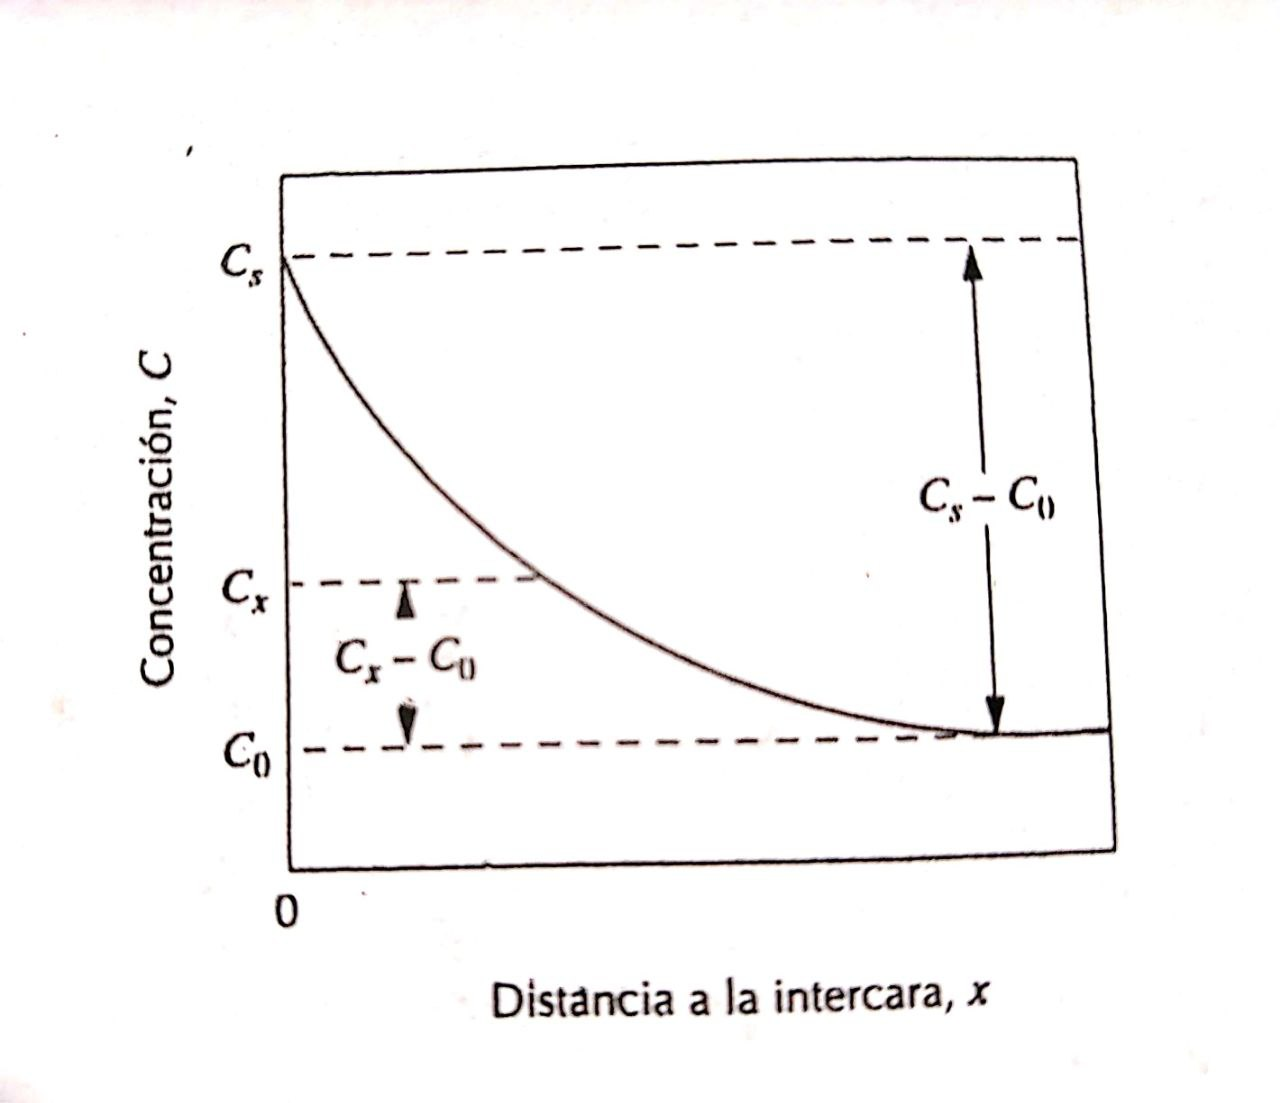


%% Boundary Conditions
Co = 0.25; %
Cs = 1.2; %
Cx = 0.8; %

x = 5*10^-4; %m
D = 1.6*10^-11; %m2/s

%% Process properties
Do = 6.2*10^-7; %m/s2
Qd = 80000; %J/mol
T = 900+273; %K

%% Lookup table data
addpath('C:\Users\lucio\Desktop\Matlab\My Projects\Transient Diffusion')
f = load('f_error.mat');
Zvalue = f.Z;
ferror = f.f;

%% Model simulation
sim('Transient_Diffussion.slx')

%% Results display
z0 = Zvalue(1, 1);
t = time(1, 1); %s
th = t/3600; %h

X = ['Time to obtain the desired concentration: ', num2str(th), ' h'];

disp(X)

Time to obtain the desired concentration: 0.66651 h
